## Opgaver

Opgave 7.55

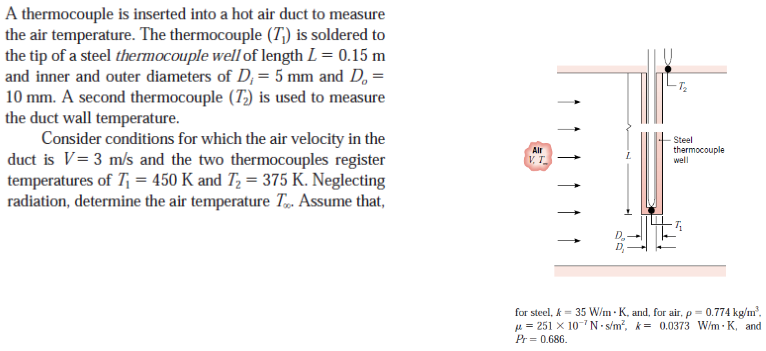

clear all
%Kendte værdiger
T1 = 450

T1 = 450

T2 = 375

T2 = 375

V = 5

V = 5

Di = 0.005

Di = 0.0050

Do = 0.008

Do = 0.0080

L = 0.1 

L = 0.1000


%Properties opslags stål:
k_steel = 35

k_steel = 35

%Properties opslags air
rho = 0.774

rho = 0.7740

my = 251e-7

my = 2.5100e-05

k_air = 0.0373

k_air = 0.0373

Pr = 0.686

Pr = 0.6860


%Vi kan se det som en finde
%Og så kan vi bruge formel 3.75 til at finde T_inf 


syms T_inf
phi = (T1 - T_inf)

$$phi = 450-T_{\inf}$$

phi_b = (T2 - T_inf)

$$phi\_b = 375-T_{\inf}$$

A = (pi/4) * (Do^2 - Di^2)

A = 3.0631e-05


%Da vi kigger fra tippen er L = x
P = pi*Do 

P = 0.0251


%Vi mangler h for at finde m så den skal vi finde. 
Re_d = (rho*V*Do)/my

Re_d = 1.2335e+03

% Vi kan nu bruge case 7.53 fra tabel 7.7 for at finde Reynolds tal. 
% Det er 7.53 da Pr er cirka 0.7 og vi bruger T_inf og Re_d 1<Re_d<10^6
%Vi skal så finde konstanterne C, m og n 
%fra tabel 7.4:
% Re_d imellem 1000-2e5 så C og m: 
C = 0.26 

C = 0.2600

m = 0.6 

m = 0.6000

% da 10 er støre en pr, så er n =
n = 0.37

n = 0.3700


%Så kan 7.53 skrives op 
Prs = Pr %I vores tilfelde da de evalueres samme sted. 

Prs = 0.6860

Nu_d = C*Re_d^m*Pr^n ((Pr / Prs)^(1/4))

Nu_d = 16.1841

h = (Nu_d * k_air)/Do 

h = 75.4585


m_fin = sqrt((h*P)/(k_steel*A)) %Fra tabel 3.4

m_fin = 42.0594

x = L %da x = L 

x = 0.1000

theta_star = (cosh(m_fin *(L-x)) + (h/(m_fin*k_steel) * sinh(m_fin*(L-x)))) / (cosh(m_fin*L) + (h/(m_fin*k_steel)*sinh(m_fin*L))) %finder phi star

theta_star = 0.0284


vpa(solve(phi/phi_b == theta_star, T_inf)) %løser for T_inf

$$ans = 452.18861984587044447706770325559$$

Opgave 7.75

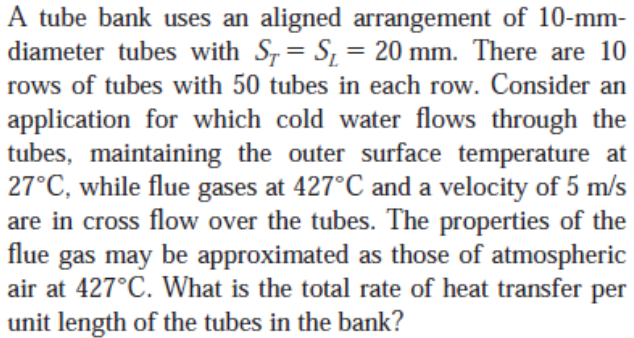

clear all 
St = 0.02

St = 0.0200

Sl = 0.02

Sl = 0.0200


Ts = 27 + 274

Ts = 301

T_initial = 427 + 274

T_initial = 701

V = 5

V = 5

D = 0.01 

D = 0.0100

syms L %Ukendt L så vi beholder dem som symbolsk bruges ikke da q' 

Nl = 10

Nl = 10

Nt = 50

Nt = 50

N = 10 * 50

N = 500

% Tabel værdiger
%luft 300k
Pr_kold = 0.707

Pr_kold = 0.7070

%luft 700k
v = 68.1E-6

v = 6.8100e-05

k = 0.0524

k = 0.0524

Pr_hot = 0.695

Pr_hot = 0.6950

rho = 0.498

rho = 0.4980

Cp = 1075

Cp = 1075


%Vi finder Raynolds igen
Vmax = (St)/(St-D)*V

Vmax = 10

Re = (Vmax*D)/v

Re = 1.4684e+03

%Der er er aligned så vi kigger i tabel 7.5 for at finde det rigtige
%altså konstanter Da vi er imellem 10^3 - 2*e5 og aligned så er C1 og m:
C1 = 0.27

C1 = 0.2700

m = 0.63

m = 0.6300

C2 = 0.97

C2 = 0.9700


%Nu kan vi finde nussels med den lange formel

Nu = C1 * C2 *Re^m * Pr_hot^0.36 * ((Pr_hot/Pr_kold)^(1/4))

Nu = 22.6208



h = (k*Nu)/D

h = 118.5332


% Nu skal vi egentlig bare have fat i newtons kølings lov
%Men hov!

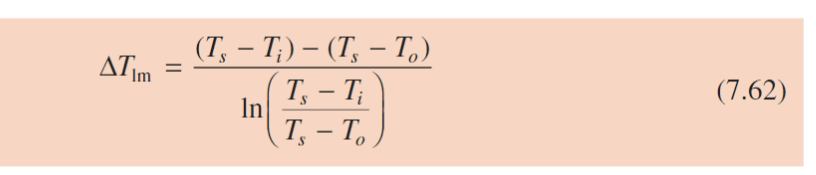

%bruges i stedet for den standard t_s - t_inf da temperaturen i fluidet
%kan ændre sig drastisk over banken. men vi kender ikke T0
%vi kan redes

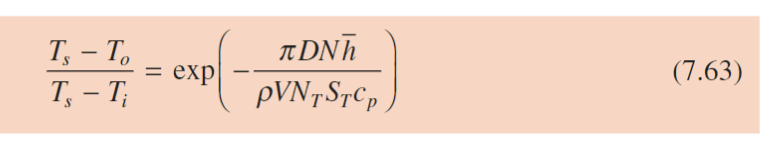

syms T_out
T_out = vpa(solve((Ts - T_out)/(Ts-T_initial) == exp(-(pi*D*N*h)/(rho*V*Nt*St*Cp)), T_out))

$$T\_out = 500.51244199236679577325048740022$$


%Så kan vi få delta T
DT  = ((Ts-T_initial) - (Ts - T_out)) / log((Ts-T_initial)/(Ts-T_out))

$$DT = -288.22747564365143343486752040987$$


% Så kan vi endelig bruge:

%Dette er newtons kølings lov uden L ganget med derfor w/m i stedet for w
%som = q = w så q' = q_mark = w/m 
q_mark = N*(h*pi*D*DT) % i W / m

$$q\_mark = -536655.07089693218648716944894679$$

q_mark / 1000 % I Kw / m 

$$ans = -536.65507089693218648716944894679$$


%Negativt tegn da varmen går i vandet. da vores assumption at vandet er
%uniform temperatur, så er det nok en dårlig assumption. 

